clc; clear all; close all;
rng(0)

Creating a neural network  for openfast based on full state estimation, it would be ideal to extend this model to include full-state estimation based only on commonly available measurements of the commercial turbine. These measurments are also available in real time; these SCADA measurments are:

1.) Tower-top acceleration

2.) Pitch angle

3.) Generator torque

4.) Rotational speed of turbine shaft

We could try to construct a traditional NN to estimate the full-state of the turbine based on the available real time data. If we do this, we could estimate things such as produced power, or loads in the tower/platform connection, and incorporate these states in the reward function. I.e high reward for energy, and a negative reward for high loads.

I'd like to keep this problem realistic, because I see potential real world application if the controller for the wind turbine only needs a "software update", that is, replacing a standard control theory controller with a Deep Reinforcement Learning NN. In the future, this means I will construct the model with the assumption I can only measure SCADA measurements, and increase complexity with a **DeepFAST** block to estimate full states based on SCADA measurements. We might need to introduce another measurment if we fail to find any significant correalation.

First we must define the observation information. In the current OpenFAST simulation, the default settings are for 99 outputs, so for simplicity, I will just use all of them (minus time).

nObsStates = 4;
obsInfo = rlNumericSpec([nObsStates 1]) ;
Neurons = 256 ;

MaxMoment = 100000 ;
Cpitch = 1 ;
Cmoment = 2.5 ;
Penalty = 5000 ;

Then define the available actuation actions, in this case, I will just be using the cable control, so changing the length of the mooring system by the fairlead, we can influence the dynamics of the system inside OpenFAST via the Simulink block. This could be further increased to blade pitch control, generator speed, and others, creating a more complex system with communication between turbine blades and mooring control.

nActStates = 3 ; % 3 Mooring Lines (3 change in lengths)
actInfo = rlNumericSpec([nActStates 1],"UpperLimit",1,"LowerLimit",-1);

We are also allowed to specify an upper and lower limit of the actuation, dimensions depend solely on the input, therefore, we are limited to changing the cable length between -1 and 1, but we scale it up with a gain filter in the Simulink diagram so the mooring lines are constrained between -6m and 6m.

Now we must create the environment from Simulink simulation using the OpenFAST S-Func block. The FAST S-Func allows us to force the turbine during the simulation, and recovering information about the states as that simulation is on going. An additional block is needed in the Simulink model to tell MATLAB "we would like to apply the reinforcement learning here", connecting the observed states, to the recommended actuations. This is the "controller" block.

env = rlSimulinkEnv("FAST_RL_Env", "FAST_RL_Env/controller",obsInfo,actInfo) ;
env.UseFastRestart = 'off' ;
Ts = 0.1;          % Sample time for RL controller, not necessarily OF time step
LearnRate = 0.005 ; % Steepness at which it will perform the gradient descent
%env.ResetFcn = @randomstart ;

We have to tell MATLAB information about the model such as the available observation info, and available actions to take in the environment

We then can create a neural network for the actions, followed by creating a neural network for the observation. These two neural networks are used to critique and update the models policy to maximize the reward.

actnet = [featureInputLayer(nObsStates,"Name","obs"),fullyConnectedLayer(Neurons,"Name",'fc1'),reluLayer("Name",'relu1'),fullyConnectedLayer(Neurons,"Name",'fc2'),reluLayer("Name",'relu2'),fullyConnectedLayer(Neurons,"Name",'fc3'),reluLayer("Name",'relu3'),fullyConnectedLayer(nActStates,"Name","act"),tanhLayer("Name","tanh"),scalingLayer("Name","scact",Scale=max(actInfo.UpperLimit))]

actnet =   1×10 Layer array with layers:

     1   'obs'     Feature Input     4 features
     2   'fc1'     Fully Connected   256 fully connected layer
     3   'relu1'   ReLU              ReLU
     4   'fc2'     Fully Connected   256 fully connected layer
     5   'relu2'   ReLU              ReLU
     6   'fc3'     Fully Connected   256 fully connected layer
     7   'relu3'   ReLU              ReLU
     8   'act'     Fully Connected   3 fully connected layer
     9   'tanh'    Tanh              Hyperbolic tangent
    10   'scact'   ScalingLayer      Scaling layer

We can use this NN to create an actor for the model, or how the NN interacts with the environment (OpenFAST)

actorOpts = rlOptimizerOptions('LearnRate',LearnRate);
actor = rlDeterministicActorRepresentation(actnet,obsInfo,actInfo,"Observation",'obs','Action','scact')

actor =   rlDeterministicActorRepresentation with properties:

         ActionInfo: [1×1 rl.util.rlNumericSpec]
    ObservationInfo: [1×1 rl.util.rlNumericSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


Create Q-Value critic for use in DDPG

obsPath = [featureInputLayer(nObsStates,"Name","obs"),fullyConnectedLayer(Neurons,"Name",'fc1'),reluLayer("Name",'relu1'),fullyConnectedLayer(Neurons,"Name",'fc2'),additionLayer(nActStates,"Name","add"),reluLayer("Name",'relu2'),fullyConnectedLayer(Neurons,"Name",'fc3'),reluLayer("Name",'relu3'),fullyConnectedLayer(1,"Name","value")];
actPath = [featureInputLayer(nActStates,"Normalization","none","Name","act")
    fullyConnectedLayer(Neurons,"Name","fcact")]

actPath =   2×1 Layer array with layers:

     1   'act'     Feature Input     3 features
     2   'fcact'   Fully Connected   256 fully connected layer

From the graph, we can see that while the state approaches -5, a positive reward is gained. It is up to the NN to determine the best way to maximize this reward by learning how its action increases the reward. We must now create the critic network, this is essentially just joining the neural nets we created in the correct way.

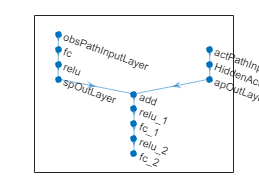

% qvalnet = layerGraph(obsPath) ;
% qvalnet = addLayers(qvalnet,actPath) ;
% for i = 2:nActStates
%     a = num2str(i) ;
%     b = 'add/in' ;
%     c = [b a] ;
%     qvalnet = connectLayers(qvalnet,'fcact',c )
% end
% plot(qvalnet)
statePath = [
    featureInputLayer( ...
        obsInfo.Dimension(1), ...
        Name="obsPathInputLayer")
    fullyConnectedLayer(Neurons)
    reluLayer
    fullyConnectedLayer(Neurons,Name="spOutLayer")
    ];

% Define action path
actionPath = [
    featureInputLayer( ...
        actInfo.Dimension(1), ...
        Name="actPathInputLayer")
    fullyConnectedLayer(Neurons, ...
        Name="HiddenActor1", ...
        BiasLearnRateFactor=0)
    fullyConnectedLayer(Neurons, ...
        Name="apOutLayer", ...
        BiasLearnRateFactor=0)
    ];

% Define common path
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(Neurons)
    reluLayer
    fullyConnectedLayer(1)
    ];

% Create layergraph, add layers and connect them
criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"spOutLayer","add/in1");
criticNetwork = connectLayers(criticNetwork,"apOutLayer","add/in2");
plot(criticNetwork)

Create the critic object based on the Q-value critic we just created and connected

% criticOpts = rlOptimizerOptions('LearnRate',LearnRate);
% critic = rlQValueRepresentation(qvalnet,obsInfo,actInfo,"Observation","obs","Action","act");
critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsPathInputLayer", ...
    ActionInputNames="actPathInputLayer");
criticOpts = rlOptimizerOptions(LearnRate=LearnRate,GradientThreshold=1);
actorOpts = rlOptimizerOptions(LearnRate=LearnRate,GradientThreshold=1);

Now we must create the agent, or the combined actor/critic of the model. This is responsible for interacting with the environment, and obtaining data about what it has done.

agentOpts = rlDDPGAgentOptions(...
                'ActorOptimizerOptions',actorOpts,...
                'CriticOptimizerOptions',criticOpts,...
                'SampleTime',Ts,...
                'MiniBatchSize',128,...
                'NumStepsToLookAhead',50,...
                'DiscountFactor',0.99);
agent = rlDDPGAgent(actor,critic,agentOpts) ;

Lets set some OpenFAST settings. TMax has to be large or else the S-Func OpenFAST block will end when this time is reached.

FAST_InputFileName = '5MW_OC4Semi_WSt_WavesWN.fst';
TMax               = 500; % seconds

Not much, lets begin training:

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',5000,...
    'MaxStepsPerEpisode',600,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',200000,...
    'ScoreAveragingWindowLength',5,...
    'SaveAgentCriteria',"EpisodeReward",...
    'SaveAgentValue',5000,Plots="training-progress");

info = train(agent,env,trainOpts) ;

 **************************************************************************************************
 OpenFAST

 Copyright (C) 2023 National Renewable Energy Laboratory
 Copyright (C) 2023 Envision Energy USA LTD

 This program is licensed under Apache License Version 2.0 and comes with ABSOLUTELY NO WARRANTY.
 See the "LICENSE" file distributed with this software for details.
 **************************************************************************************************

 OpenFAST-v3.4.1
 Compile Info:
  - Compiler: Intel(R) Fortran Compiler 2021
  - Architecture: 64 bit
  - Precision: single
  - OpenMP: No
  - Date: Feb 11 2023
  - Time: 19:51:48
 Execution Info:
  - Date: 04/21/2023
  - Time: 21:06:08-0400

 OpenFAST input file heading:
     FAST Certification Test #25: NREL 5.0 MW Baseline Wind Turbine with OC4-DeepCwind semi
     configuration, for use in offshore analysis

 Running ElastoDyn.
 Nodal outputs section of ElastoDyn input file not found or improperly formatted.
 Ru

FAST_Solution:FAST_AdvanceStates:AD_UpdateStates:BEMT_UpdateStates:UpdatePhi(node 5, blade 3):BEMT_UnCoupledSolve:There is no valid value of phi for these operating conditions: Vx = 47.493, Vy = -4.0504, rlocal = 11.723, theta = 1.0732, geometric phi = 1.6559. This warning will not be repeated though the condition may persist. (See GeomPhi output channel.)

  OpenFAST completed.



Would be nice to visualize this data while it trains. If you click on the plots of mooring line change in length and pitch in the simulink diagram, you can actually watch the NN try different approaches to moving the mooring lines and what it does the pitch in the OpenFAST simulation.

This might seem like overkill for mooring line control, but it allows the easy addition of other control aspects, and the control of multiple turbines all at once.